**Klasszikus ortogonális polinomok**

**Hermite polinom**


$$[-\infty; \infty], \quad w(x) = e^{-x^2},\\
H_0(x) = 1, \quad H_1(x) = 2x,\\
H_{n+1}(x) =\ 2x \cdot H_n(x) -
2n \cdot  H_{n-1}(x) \quad (n = 1, 2, . . .).$$



$$H_2(x) = 2x \cdot H_1(x) - 2\cdot  H_0(x) = 4x^2-2
$$



$$H_3(x) =2x \cdot H_2(x) -4\cdot  H_1(x) = 
2x(4x^2-2)-4\cdot 2x = 8x^3-12x$$


N=5;
H=zeros(N+1,N+1);
Hef=zeros(N+1,N+1);
H(1,N+1)=1;
H(2,N)=2;
for k=2:N
H(k+1,1:N+1)=2*[H(k,2:N+1),0]-2*(k-1)*H(k-1,1:N+1);
end
H

H =      0     0     0     0     0     1
     0     0     0     0     2     0
     0     0     0     4     0    -2
     0     0     8     0   -12     0
     0    16     0   -48     0    12
    32     0  -160     0   120     0



for k=0:N
Hef(k+1,:)=H(k+1,:)/H(k+1,N-k+1);
end
Hef

Hef =          0         0         0         0         0    1.0000
         0         0         0         0    1.0000         0
         0         0         0    1.0000         0   -0.5000
         0         0    1.0000         0   -1.5000         0
         0    1.0000         0   -3.0000         0    0.7500
    1.0000         0   -5.0000         0    3.7500         0


Rajzoljuk ki az egy főegyütthatós Hermite polinomokat!

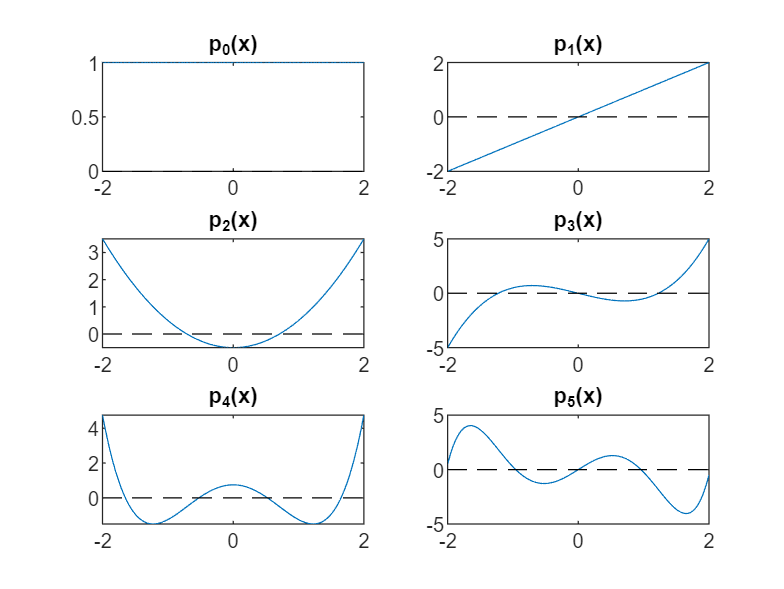

a=2;
xx=linspace(-a,a,100);

for k=1:6
    subplot(3,2,k)
    pk=Hef(k,:);
    ppk=polyval(pk,xx);
    plot(xx,ppk,'-',xx,0*xx,'k--');
    title(sprintf('p_%d(x)',k-1));
end